##     Задание 3. Увеличение резкости.

I = double(imread("images/house.jpg"))/255;
[height, width, numberOfColorChannels] = size(I);

IR = I(:, :, 1); % red_Channel
IG = I(:, :, 2); % green_Channel
IB = I(:, :, 3); % blue_Channel

Создадим матрицу ядра увеличения резкости

sharp = reshape([[0, -1, 0];[-1, 5, -1];[0, -1, 0]], 3, 3);

Теперь будем сворачивать с изображением

IR_SHARP1 = conv2(IR, sharp); IG_SHARP1 = conv2(IG, sharp); IB_SHARP1 = conv2(IB, sharp); % 1 times
IR_SHARP2 = conv2(IR_SHARP1, sharp); IG_SHARP2 = conv2(IG_SHARP1, sharp); IB_SHARP2 = conv2(IB_SHARP1, sharp); % 2 times
IR_SHARP3 = conv2(IR_SHARP2, sharp); IG_SHARP3 = conv2(IG_SHARP2, sharp); IB_SHARP3 = conv2(IB_SHARP2, sharp); % 3 times

Сохраним, чтобы посмотреть на то насколько резким стало изображение... (заметно ли?)

I_SHARP1 = cat(3, IR_SHARP1, IG_SHARP1, IB_SHARP1);
I_SHARP2 = cat(3, IR_SHARP2, IG_SHARP2, IB_SHARP2);
I_SHARP3 = cat(3, IR_SHARP3, IG_SHARP3, IB_SHARP3);

I_ORIGINAL = cat(3, IR, IG, IB);

imwrite(I_SHARP1, 'house_SHARP1.png');
imwrite(I_SHARP2, 'house_SHARP2.png');
imwrite(I_SHARP3, 'house_SHARP3.png');

imwrite(I_ORIGINAL, 'house_re.png');

Теперь переходим к анализу Фурье-образов...

*Найдите Фурье-образ от исходного изображения и от каждого из ядер, заполнив пропуски нулями....*

Теперь мы нашли Фурье-образ оригинала и каждого из ядер - перемножим их поэлементно и проверим истинность теоремы о Свёртке...

IR_FFT =  (fft2(IR)); 
IG_FFT =  (fft2(IG));
IB_FFT =  (fft2(IB));
SHARP_FFT = (fft2(sharp, height, width));

*Так как операция свёртки - ассоциативна, то можно также и расширить теорему о свёртке - если будем перемножать образы несколько раз, то и свёртка будет применяться не один раз, взгляните просто ниже:*

IR_SHARP1 = IR_FFT.*SHARP_FFT; IG_SHARP1 = IG_FFT.*SHARP_FFT; IB_SHARP1 = IB_FFT.*SHARP_FFT;
IR_SHARP2 = IR_FFT.*SHARP_FFT.*SHARP_FFT; IG_SHARP2 = IG_FFT.*SHARP_FFT.*SHARP_FFT; IB_SHARP2 = IB_FFT.*SHARP_FFT.*SHARP_FFT;
IR_SHARP3 = IR_FFT.*SHARP_FFT.*SHARP_FFT.*SHARP_FFT; IG_SHARP3 = IG_FFT.*SHARP_FFT.*SHARP_FFT.*SHARP_FFT; IB_SHARP3 = IB_FFT.*SHARP_FFT.*SHARP_FFT.*SHARP_FFT;

Не забудем выполнить обратное преобразование Фурье

IR_SHARP1 = ifft2(IR_SHARP1); IG_SHARP1 = ifft2(IG_SHARP1); IB_SHARP1 = ifft2(IB_SHARP1);
IR_SHARP2 = ifft2(IR_SHARP2); IG_SHARP2 = ifft2(IG_SHARP2); IB_SHARP2 = ifft2(IB_SHARP2);
IR_SHARP3 = ifft2(IR_SHARP3); IG_SHARP3 = ifft2(IG_SHARP3); IB_SHARP3 = ifft2(IB_SHARP3);

Теперь сохраняем ново-полученные изображения, чтобы сравнить...

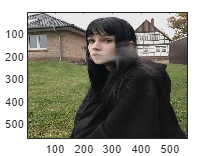

I_SHARP1 = cat(3, IR_SHARP1, IG_SHARP1, IB_SHARP1);
I_SHARP2 = cat(3, IR_SHARP2, IG_SHARP2, IB_SHARP2);
I_SHARP3 = cat(3, IR_SHARP3, IG_SHARP3, IB_SHARP3);

imagesc(I_ORIGINAL)


imwrite(I_SHARP1, 'house2_SHARP1.png');
imwrite(I_SHARP2, 'house2_SHARP2.png');
imwrite(I_SHARP3, 'house2_SHARP3.png');